## Import the data

 
close all hidden 
clearvars hidden force
clearvars global force
fileNamesStr = "";
[fileNames, folder] = uigetfile('*.csv', 'MultiSelect','on');
warning('off', 'MATLAB:table:ModifiedAndSavedVarnames');
dataTables = cellfun(@(x) readtable(fullfile(folder, x),  'Format','%f%f',"VariableNamingRule","preserve"), fileNames, UniformOutput=false);
[~, fileNames, ~] = fileparts(fileNames);
fileNamesStr = string(fileNames)

## Watch Data

selName = fileNamesStr(1);

Unrecognized function or variable 'fileNamesStr'.

index = find(strcmp(fileNamesStr,selName));
plot(dataTables{index},"Time (s)","Outer Diameter (%)")
title(fileNamesStr(index), 'Interpreter','none')

## Select for joining

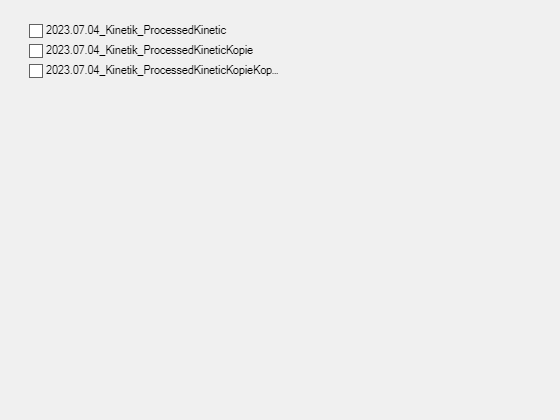

 
fig = uifigure;
for k=1:numel(dataTables)
cbh(k) = uicontrol(fig,'Style','checkbox','String',fileNamesStr(k), ...
'Value',0,'Position',[30 400-20*k 250 20]);
end

## Select start

%Plot und KlickKlick
%Anpassen von X Achse


## Join

 
ix = [];
for i = cbh
    ix = [ix i.Value];
end
index = 1:numel(cbh);
index = index(logical(ix));
joinedData = outerjoin(dataTables{index(1:2)}, "Keys","Time (s)","MergeKeys",true);
for i = 3:numel(index)
    selIndex = index(i);
    joinedData = outerjoin(joinedData, dataTables{selIndex}, "Keys","Time (s)","MergeKeys",true);
end
joinedData

joinedData = 12972×4 table
    Time (s)    Outer Diameter (%)_left    Outer Diameter (%)_right    Outer Diameter (%)
    ________    _______________________    ________________________    __________________

        0                 71                          71                       71        
      0.1                 71                          71                       71        
      0.2                 71                          71                       71        
      0.3                 71                          71                       71        
      0.4                 71                          71                       71        
      0.5                 71                          71                       71        
      0.6                 71                          71                       71        
      0.7                 

## Create Median

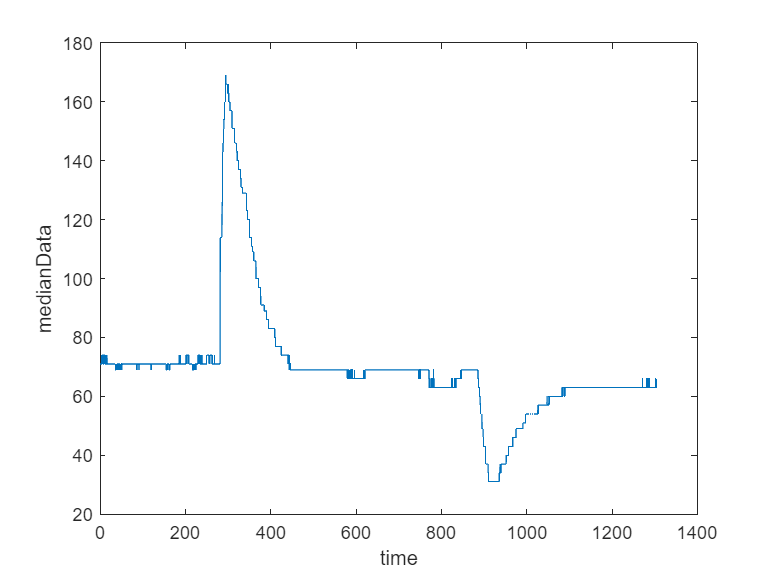

 
addpath stdshade
medianData = median(joinedData{:,2:end}, 2);
sdData = std(joinedData{:,2:end},0, 2);
time = joinedData.("Time (s)");
medianTable = table(time, medianData, sdData);
figure
plot(medianTable,"time", "medianData");

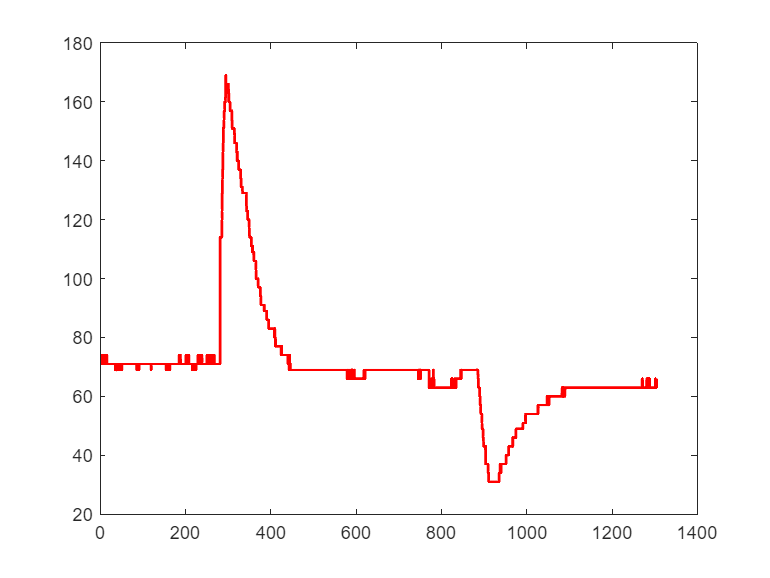

dat = joinedData{:,2:end};
figure
stdshade(dat',0.1, 'r', time);

## Save

 
[folder, file] = uiputfile(append(name,'.csv'));
writetable(medianTable, fullfile(file,folder),'Delimiter',';');
